# Ch01 MATLAB 界面与 Live Script 工作流

**本章目标 / Learning objectives**

1. 熟悉 MATLAB 主要界面区域。 2. 理解 Live Script 为什么适合做科研学习笔记。 3. 学会用代码节组织“解释 + 计算 + 图 + 结论”。

Key terms: command window, workspace, current folder, editor, live editor, run section

clear; clc; close all;
if exist("startup_learning", "file") == 2
    learningRoot = startup_learning();
else
    learningRoot = fileparts(fileparts(mfilename("fullpath")));
    addpath(learningRoot);
    addpath(fullfile(learningRoot, "functions"));
end


MATLAB fusion learning library is ready.
Root: E:\桌面\matlab学习
Chapters: E:\桌面\matlab学习\chapters
Functions: E:\桌面\matlab学习\functions\+fusionlearn
MATLAB version: 25.2.0.2998904 (R2025b)
Installed products detected: 111
Next step: open chapters/Ch00_如何使用这套讲义.mlx



## 1. MATLAB 界面区域

你需要逐步熟悉这些区域：

Command Window：直接输入命令。 Workspace：查看当前变量。 Current Folder：当前文件夹。 Editor：编辑普通 .m 文件。 Live Editor：编辑 .mlx 文件，可以混合文本、公式、代码和输出。 Figure：显示图形。

建议你学习时一直打开 Workspace 面板，这样能看到变量如何出现和变化。

a = 3;
b = 8;
c = sqrt(a^2 + b^2);
fprintf("c = %.2f\n", c);

c = 8.54


## 2. Live Script 的代码节

在 .m 或 .mlx 中，两个百分号开头的行表示一个代码节。 在 Live Editor 中可以选择 Run Section，只运行当前节。

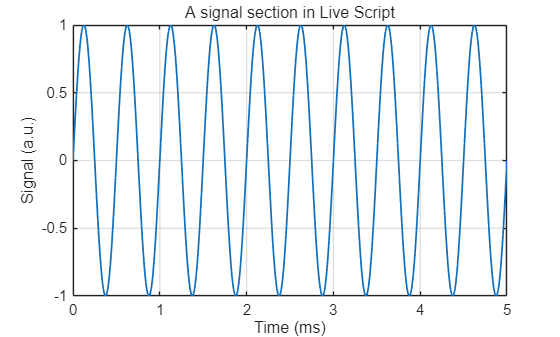

time_ms = linspace(0, 5, 501);
frequency_kHz = 2;
signal = sin(2*pi*frequency_kHz*time_ms);

figure("Color", "w");
plot(time_ms, signal, "LineWidth", 1.3);
xlabel("Time (ms)");
ylabel("Signal (a.u.)");
title("A signal section in Live Script");
grid on;
fusionlearn.plot.applyResearchStyle(gca);

## 3. 在讲义里写观察结论

运行上面的代码后，你应该观察：

1. Workspace 中出现 time_ms、frequency_kHz、signal。 2. signal 的长度和 time_ms 一样。 3. 频率 frequency_kHz 改大后，单位时间内振荡次数变多。

English sentence: The signal oscillates faster when the frequency is increased.

## 4. 清理工作区和图窗

常用命令：

clear 清除变量 clc 清空命令行显示 close all 关闭图窗

初学时不建议在每个小节都 clear，否则容易看不到变量之间的关系。

variableNames = who;
disp("Variables currently in workspace:");
disp(variableNames);

## 5. 常见错误 / Common mistakes

错误 1：以为 Live Script 只是“漂亮版脚本”。 更准确：它是科研笔记、教学讲义、交互实验记录的混合体。

错误 2：每运行一行都 clear all。 这样会让代码依赖关系难以观察。建议一章开始 clear，一节内部不要乱清。

错误 3：只看图不看变量尺寸。 科研脚本里，size、numel、class 经常比图更早暴露问题。

## 6. 练习

练习 1：创建变量 shot = 13653，并在 Workspace 中找到它。 练习 2：创建 time_ms = 0:0.1:10。 练习 3：画 sin(2*pi*0.5*time_ms)。 练习 4：把图标题改成英文 "Demo fluctuation signal"。 练习 5：用 who 查看当前变量名。

## 7. 参考答案

shot = 13653;
time_ms_answer = 0:0.1:10;
signal_answer = sin(2*pi*0.5*time_ms_answer);

figure("Color", "w");
plot(time_ms_answer, signal_answer, "LineWidth", 1.3);
xlabel("Time (ms)");
ylabel("Amplitude (a.u.)");
title("Demo fluctuation signal");
grid on;
fusionlearn.plot.applyResearchStyle(gca);

disp(who);
assert(shot == 13653);
assert(numel(time_ms_answer) == numel(signal_answer));

## 8. 本章检查表

[ ] 我知道 Command Window 的作用。 [ ] 我知道 Workspace 的作用。 [ ] 我能用 Run Section 分节运行。 [ ] 我能在 Live Script 中写代码和观察结论。 [ ] 我能用 who 查看变量。